# Transition from 1D to 2D

clear all, close all, clc
set_defaults()

## Dimension independent syntax

One benefit of the operator implementation is that it hides the details of the coordinate system and spatial dimensions similar to the dyadic notation (div, grad, curl). Consider the instantaneous problem for the continental geotherm in both 1D and 2D:

Heat equation:        $-\nabla\cdot\left[\kappa(\mathbf{x})\nabla T\right] = \rho H_0 e^{-y/h_r}$     on   $x \in \left[0,\,L\right]\quad\times\quad y \in \left[0, h\right]$

BC:         $T(x,z=0) = T_s$   and     $\left.\mathbf{q}\cdot\hat{\mathbf{z}}\right|_{z=h} = q_m$.

where $x$ is the horizontal and $y$ is the depth below the surface. Here $h$, $\rho$, $H_0$, and $\kappa$ are the thickness, density, surface heat production and thermal conductivity of the crust, respectively. The surface temperature is $T_s$ and the mantle heat flux is $q_m$. For constant parameters the solution varies only in the $y$-direction and ithe temperature, $T$ and the heat flux $q$ are given by

$T = T_0+\left(\frac{q_m}{\kappa}-\frac{\rho H_0h_r}{k}e^{-h/h_r}\right)z+\frac{\rho H_0 h_r^2}{k}(1-e^{-z/h_r})$ and $q=-q_m-\rho H_0h_r \left(e^{-z/h_r}-e^{-h/h_r}\right)$.

This problem can be solved as a 1D or a 2D problem and we'll use it here to illustrate the similarites between 1D and 2D implementations. We assume the following parameters:


rho = 2700;   % ave. crustal density [kg/m^3]
H0 = 9.6e-10; % heat production near surface [W/kg]
h = 35e3;     % ave. depth of crust [m]
Len = 10e3;     % Horizontal dimension [m]
kappa = 3.35; % thermal conductivity [W/(m K)]
T0 = 14;      % mean surface temperature [K]
hr = 10e3;    % Decay depth of heat production [m]
qm = 17e-3;   % mantle heat flow [W/m^2]

q = @(y) -qm-rho*H0*hr*(exp(-y/hr)-exp(-h/hr));
T = @(y) T0 + (qm/kappa-rho*H0*hr/kappa*exp(-h/hr))*y + rho*H0*hr^2/kappa*(1-exp(-y/hr));

One of the main aims of the operator implementation is to hide the dimensionality and coordinate system in the same way that the dyadic notation hides these details. Therefore, nothing will change on the highest layer of your code - as demonstrated in the example below.

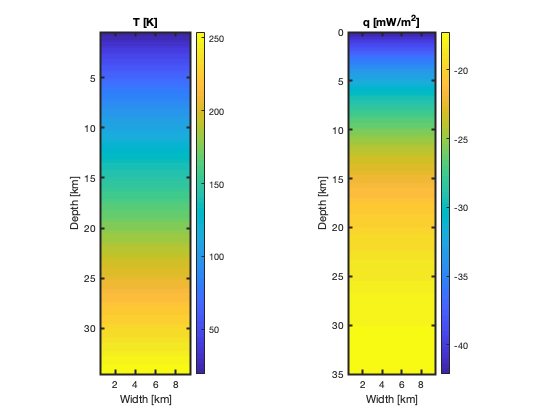

clear Grid
% Define the grid and operators
Grid.xmin = 0; Grid.xmax = Len; Grid.Nx = 10; % The only line that changes
Grid.ymin = 0; Grid.ymax = h; Grid.Ny = 40;  
Grid = build_grid(Grid);
[Xc,Yc] = meshgrid(Grid.xc,Grid.yc);
[D,G,I] = build_ops(Grid);
L = -D*kappa*G; fs = rho*H0*exp(-Yc(:)/hr);

% Define the boundary conditions
BC.dof_dir   = Grid.dof_ymin;
BC.dof_f_dir = Grid.dof_f_ymin;
BC.g         = T(Yc(Grid.dof_ymin));
BC.dof_neu   = Grid.dof_ymax;
BC.dof_f_neu = Grid.dof_f_ymax;
BC.qb        = qm*ones(Grid.Nx,1);
[B,N,fn] = build_bnd(BC,Grid,I);

% Solve for temperature
u = solve_lbvp(L,fs+fn,B,BC.g,N);
qnum = comp_flux(D,kappa,G,u,fs,Grid,BC);

% Plot solution
plot_solution(u,qnum,Grid,Xc,Yc);

qs_1D = -qnum(Grid.dof_f_ymin(1))*1e3;

## Changes to main functions

Of course, the changes required to go from 1D to 2D are just hidden in the functions that have been called. The following functions you have written must be updated:

- `build_grid()`: need to add all the information about the 2D grid - substantial change (trivial)

- `build_ops()`: implement 2D operators - substantial change (not trivial: Lectures 16, 17)

- **comp_mean()**: need to update averaging to 2D (requires some thought)

- **flux_upwind()**: implement 2D matrix (non trivial but clean)

The following functions that do **not** need to be changed:

- `build_bnd()`

- `solve_lbvp()`

- `comp_flux()`

These functions don't change, because the BC's are implemented as an elimination of constraints, which is independent of dimension. Benefit of the slightly more abstract approach.

## Of course, life in 2D is much more interesting ...

For example we could have a region of increased heat production, for example a large granitic pluton. Given that our standard sirface properties are for granite we can keep them constant within the pluton.

R_pluton = 4e3;    % radius of pluton
y_cen_pluton = 5e3;  % depth of the center of the pluton

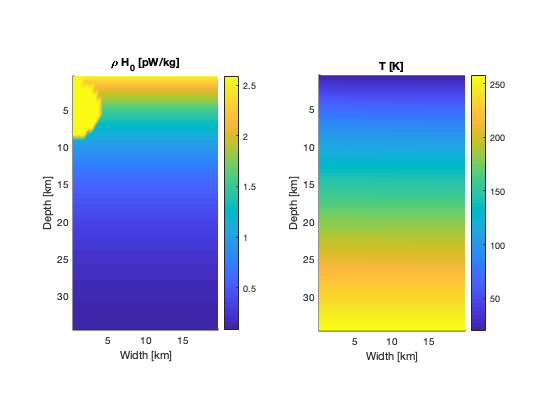

clear Grid
% Define the grid and operators
Grid.xmin = 0; Grid.xmax = 2*Len; Grid.Nx = 40; % The only line that changes
Grid.ymin = 0; Grid.ymax = h; Grid.Ny = 40;  
Grid = build_grid(Grid);
[Xc,Yc] = meshgrid(Grid.xc,Grid.yc);
[D,G,I] = build_ops(Grid);
L = -D*kappa*G; 
fs = rho*H0*exp(-Yc(:)/hr);
% Add pluton
distance = sqrt(Xc(:).^2+(Yc(:)-y_cen_pluton).^2);
fs(distance<=R_pluton) = rho*H0;

% Define the boundary conditions
BC.dof_dir   = Grid.dof_ymin;
BC.dof_f_dir = Grid.dof_f_ymin;
BC.g         = T(Yc(Grid.dof_ymin));
BC.dof_neu   = Grid.dof_ymax;
BC.dof_f_neu = Grid.dof_f_ymax;
BC.qb        = qm*ones(Grid.Nx,1);
[B,N,fn] = build_bnd(BC,Grid,I);

% Solve for temperature
u = solve_lbvp(L,fs+fn,B,BC.g,N);

% Plot solution
figure
subplot 121
surf(Xc/1e3,Yc/1e3,reshape(fs*1e12,Grid.Ny,Grid.Nx)/1e6), shading interp, view(2)
colorbar
xlabel 'Width [km]', ylabel 'Depth [km]', title '\rho H_0 [pW/kg]'
set(gca,'YDir','reverse')
axis equal tight

subplot 122
surf(Xc/1e3,Yc/1e3,reshape(u,Grid.Ny,Grid.Nx)), shading interp, view(2)
colorbar
xlabel 'Width [km]', ylabel 'Depth [km]', title 'T [K]'
set(gca,'YDir','reverse')
axis equal tight

While the temperature field itself does not seem to be perturbed very much the surface heat flow changes measurably due to the added heat production.

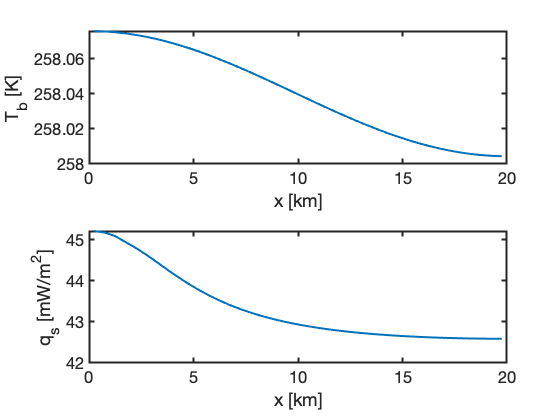

qnum = comp_flux(D,kappa,G,u,fs,Grid,BC);
qs = -qnum(Grid.dof_f_ymin)*1e3;
Tb = u(Grid.dof_ymax);

figure
subplot 211
plot(Grid.xc/1e3,Tb)
xlabel 'x [km]', ylabel 'T_b [K]'

subplot 212
plot(Grid.xc/1e3,qs)
xlabel 'x [km]', ylabel 'q_s [mW/m^2]'

# Auxillary functions

## set_defaults()

function [] = set_defaults()
set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end

function []=plot_solution(u,q,Grid,Xc,Yc)
if Grid.Nx == 1
    subplot 121
    plot(u,Grid.yc/1e3,'-')
    xlabel 'T [K]', ylabel 'Depth [km]'
    set(gca,'YDir','reverse')
    
    subplot 122
    plot(q*1e3,Grid.yf/1e3,'-')
    xlabel 'q [mW/m^2]', ylabel 'Depth [km]'
    set(gca,'YDir','reverse')
    
else
    [Xy,Yy] = meshgrid(Grid.xc,Grid.yf);
    subplot 121
    [C,h] = contourf(Xc/1e3,Yc/1e3,reshape(u,Grid.Ny,Grid.Nx),100); colorbar
    set(h,'LineColor','none')
    xlabel 'Width [km]', ylabel 'Depth [km]', title 'T [K]'
    set(gca,'YDir','reverse')
    axis equal tight
    
    subplot 122
    [C,h] = contourf(Xy/1e3,Yy/1e3,reshape(q(Grid.Nfx+1:Grid.Nf)*1e3,Grid.Ny+1,Grid.Nx),100); colorbar
    set(h,'LineColor','none')
    xlabel 'Width [km]', ylabel 'Depth [km]', title 'q [mW/m^2]'
    set(gca,'YDir','reverse')
    axis equal tight
end
end